aging = readtable('age_metabolomics.xlsx')

aging = 302×444 table
    sex     age      menopause    Carnitine    Betaine    Choline    Dimethyl_glycine    Sarcosine    Trimethyl_amine_N_oxide    Carnitine_1    Octadecenoyl_carnitine    Acetyl_carnitine    Alanine    Arginine    Asparagine    AsparticAcid    Glutamine    Histidine    Isoleucine    Leucine    Lysine    Methionine    Ornithine    Phenyl_alanine    Proline    Serine    Threonine    Tryptophan    Tyrosine    Valine    Creatinine    Kynurenine

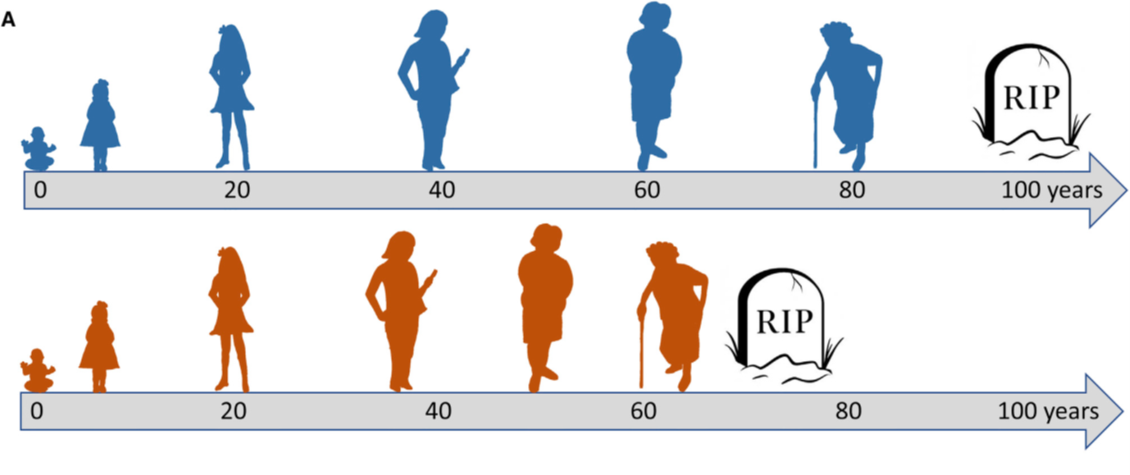  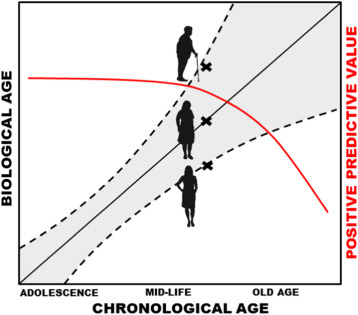     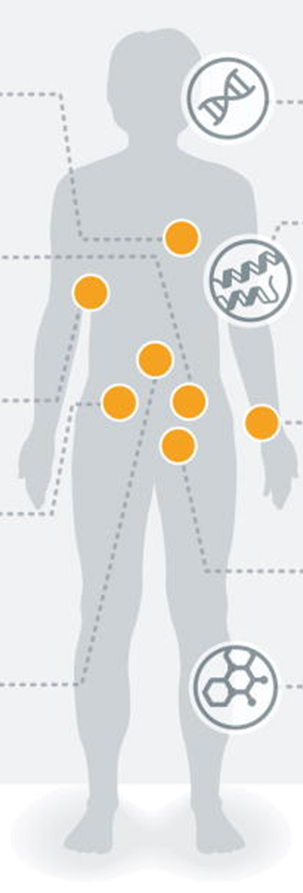


% build regression model to predict age
X = aging(:,4:end);
Y = aging.age;


Decision_Tree = fitrtree(X, Y) 

Decision_Tree =   RegressionTree
             ResponseName: 'Y'
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 300


  Properties, Methods


view(Decision_Tree)


Decision tree for regression
  1  if unknown2_74<2.16069e+06 then node 2 elseif unknown2_74>=2.16069e+06 then node 3 else 47.5043
  2  if Sphingo_myelinC16_1<11.142 then node 4 elseif Sphingo_myelinC16_1>=11.142 then node 5 else 36.8787
  3  if Glucose4<6.59949e+06 then node 6 elseif Glucose4>=6.59949e+06 then node 7 else 57.7132
  4  if Trimethyl_amine_N_oxide<11.505 then node 8 elseif Trimethyl_amine_N_oxide>=11.505 then node 9 else 30.892
  5  if Glucose12<1.60454e+07 then node 10 elseif Glucose12>=1.60454e+07 then node 11 else 44.6427
  6  if unknown3_31<1.08195e+06 then node 12 elseif unknown3_31>=1.08195e+06 then node 13 else 44.4269
  7  if probablyErythronicAcidTMS4<1.10652e+06 then node 14 elseif probablyErythronicAcidTMS4>=1.10652e+06 then node 15 else 61.3669
  8  if unknown2_92<2.40892e+06 then node 16 elseif unknown2_92>=2.40892e+06 then node 17 else 29.9261
  9  fit = 56.6491
 10  if Lyso_phosphatidyl_cholineC18_0<36.3207 then node 18 elseif Lyso_phosphatidyl_cholineC18_

%Examine resubsitution error
resuberror = resubLoss(Decision_Tree)

resuberror = 14.5674

% cross validation error
[E,SE,Nleaf] = cvloss(Decision_Tree)

E = 241.4726

SE = 1.3348

Nleaf = 54

% prune the tree
[E,SE,Nleaf,Best_prune_level] = cvloss(Decision_Tree,'subtrees','all')  

E =   216.8623
  216.8860
  216.8559
  216.6869
  216.5111
  216.1066
  214.9491
  214.9261
  214.9261
  213.7239


SE =     1.0318
    1.0317
    1.0318
    1.0378
    1.0373
    1.0372
    1.0371
    1.0371
    1.0371
    1.0320


Nleaf =     54
    53
    52
    51
    50
    49
    48
    47
    46
    45


Best_prune_level = 44

prune_tree = prune(Decision_Tree,'Level',Best_prune_level); 
view(prune_tree)


Decision tree for regression
 1  if unknown2_74<2.16069e+06 then node 2 elseif unknown2_74>=2.16069e+06 then node 3 else 47.5043
 2  if Sphingo_myelinC16_1<11.142 then node 4 elseif Sphingo_myelinC16_1>=11.142 then node 5 else 36.8787
 3  if Glucose4<6.59949e+06 then node 6 elseif Glucose4>=6.59949e+06 then node 7 else 57.7132
 4  fit = 30.892
 5  if Glucose12<1.60454e+07 then node 8 elseif Glucose12>=1.60454e+07 then node 9 else 44.6427
 6  if unknown3_31<1.08195e+06 then node 10 elseif unknown3_31>=1.08195e+06 then node 11 else 44.4269
 7  if probablyErythronicAcidTMS4<1.10652e+06 then node 12 elseif probablyErythronicAcidTMS4>=1.10652e+06 then node 13 else 61.3669
 8  fit = 36.7689
 9  if unknown7_07<711769 then node 14 elseif unknown7_07>=711769 then node 15 else 54.1456
10  fit = 50.4939
11  fit = 28.2483
12  fit = 54.8565
13  fit = 64.4589
14  fit = 58.837
15  fit = 31.6268



% do hold out validation
[Xtrain, Ytrain, Xtest, Ytest] = trainTestSplit(X,Y,0.7);

Grow a regression tree using the training set.

Decision_Tree = fitrtree(Xtrain, Ytrain)

Decision_Tree =   RegressionTree
             ResponseName: 'Y'
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 209


  Properties, Methods


% prune the tree
[E,SE,Nleaf,Best_prune_level] = cvloss(Decision_Tree,'subtrees','all')  

E =   240.7750
  240.7750
  240.7218
  240.0485
  240.1205
  239.9158
  239.3735
  238.1151
  237.4749
  235.2858


SE =     1.7843
    1.7843
    1.7837
    1.7789
    1.7794
    1.7795
    1.7793
    1.7580
    1.7567
    1.7434


Nleaf =     37
    36
    35
    34
    33
    32
    31
    30
    29
    28


Best_prune_level = 31

prune_tree = prune(Decision_Tree,'Level',Best_prune_level)

prune_tree =   RegressionTree
             ResponseName: 'Y'
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 209


  Properties, Methods


YPred = predict(prune_tree,Xtest)

YPred =    61.8978
   61.8978
   52.7260
   61.8978
   29.5297
   34.9589
   61.8978
   61.8978
   29.5297
   34.9589


% compare with Ytest
corr(YPred, Ytest)

ans = 0.6096

% use original tree
YPred = predict(Decision_Tree,Xtest)

YPred =    70.0999
   64.2730
   50.8610
   54.8377
   31.3659
   22.1835
   54.9207
   54.9207
   23.8756
   30.2555


% compare with Ytest
corr(YPred, Ytest)

ans = 0.5196

% optimize hyperparameters

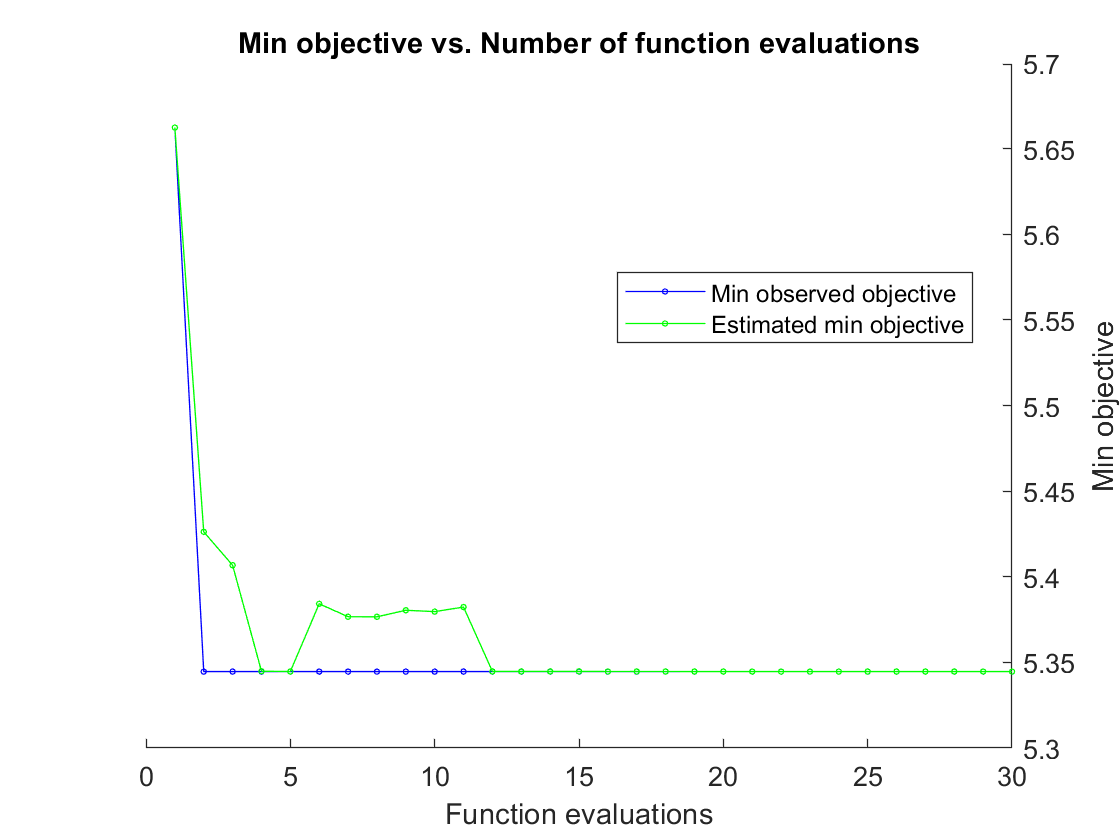

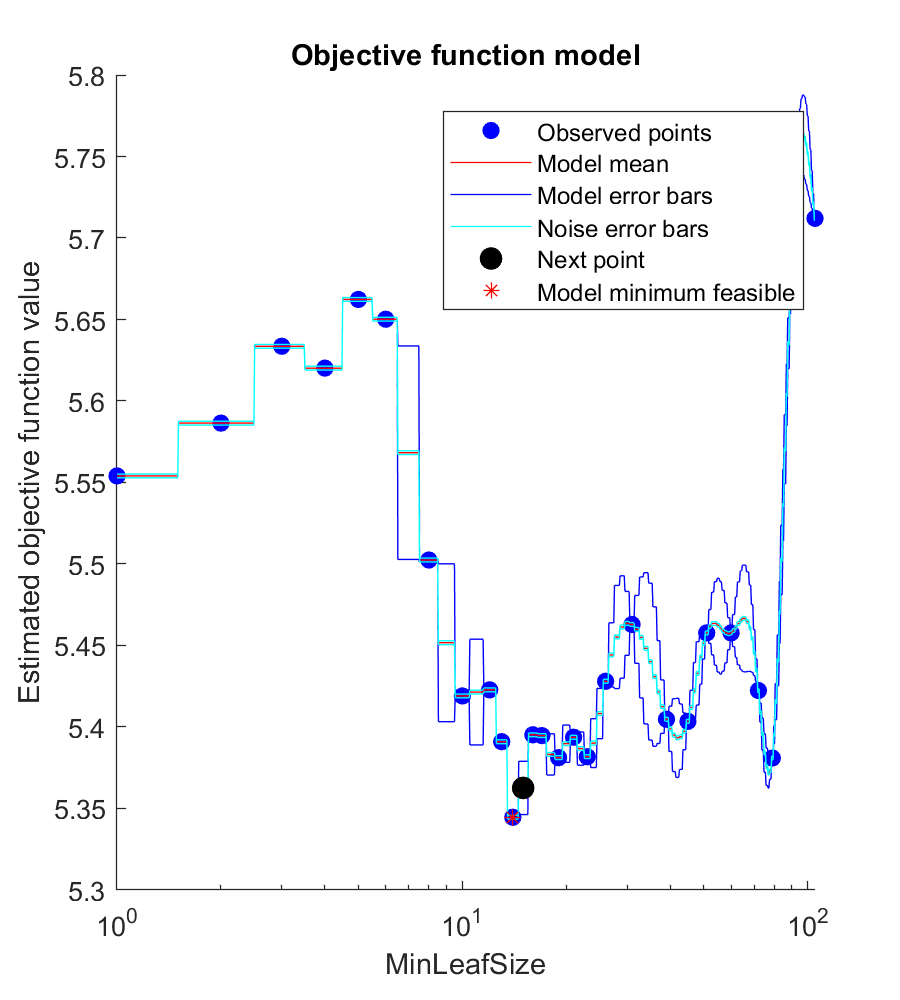

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |      5.6623 |      1.4161 |      5.6623 |      5.6623 |            5 |
|    2 | Best   |      5.3446 |      1.1456 |      5.3446 |      5.4262 |           14 |
|    3 | Accept |      5.4577 |     0.76585 |      5.3446 |      5.4067 |           60 |
|    4 | Accept |      5.5864 |      1.4915 |      5.3446 |      5.3448 |            2 |
|    5 | Accept |      5.3952 |     0.88082 |      5.3446 |      5.3447 |           16 |
|    6 | Accept |      5.4228 |         1.1 |      5.3446 |      5.3842 |           12 |
|    7 | Accept |      5.3818 |     0.82069 |      5.3446 |      5.3767 |           23 |
|    8 | Accept |    

Mdl =   RegressionTree
                         ResponseName: 'Y'
                CategoricalPredictors: []
                    ResponseTransform: 'none'
                      NumObservations: 209
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]


  Properties, Methods


Mdl = fitrtree(Xtrain,Ytrain,'OptimizeHyperparameters','auto')

YPred = predict(Mdl,Xtest)

YPred =    60.2191
   69.5415
   58.6618
   60.2191
   23.5788
   28.5531
   69.5415
   69.5415
   36.9173
   28.5531


corr(YPred, Ytest)

ans = 0.5709

% find important features
imp = predictorImportance(Mdl) % also works for classification trees

imp =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.7264         0    0.0791         0         0         0         0         0


t1 = aging.Properties.VariableNames(4:end);

t2 = table(t1', imp')

t2 = 441×2 table
              Var1               Var2
    _________________________    ____

    'Carnitine'                   0  
    'Betaine'                     0  
    'Choline'                     0  
    'Dimethyl_glycine'            0  
    'Sarcosine'                   0  
    'Trimethyl_amine_N_oxide'     0  
    'Carnitine_1'                 0  
    'Octadecenoyl_carnitine'      0  
    'Acetyl_carnitine'            0  
    'Alanine'                     0  
    'Arginine'                    0  
    'Asparagine'                  0  
    'AsparticAcid'                0  
    'Glutamine'                   0  
    'Histidine'                   0  
    'Isoleucine'                  0  



t2 = sortrows(t2,'Var2','descend')

t2 = 441×2 table
                   Var1                    Var2  
    __________________________________    _______

    'unknown0_94'                          11.254
    'Sphingo_myelinC16_1'                  3.5629
    'Glucose9'                             2.6432
    'unknown3_94'                          1.0544
    'Glucose1'                            0.98777
    'Valine2'                              0.8571
    'Lyso_phosphatidyl_cholineC28_1'      0.72643
    'unknown1_55'                         0.67316
    'Creatinine2'                         0.49625
    'Diacyl_phosphatidyl_cholineC32_0'     0.0791
    'Carnitine'                                 0
    'Betaine'                                   0
    'Choline'                                   0
    'Dimethyl_glycine'                          0
    'Sarcosine'                                 0
    'Trimethyl_amine_N_oxide'                   0



% RANDOM FORESTS WITH 200 TREES
RFmodel = TreeBagger(200, Xtrain, Ytrain,'Method','regression','OOBPrediction','On')

RFmodel =   TreeBagger
Ensemble with 200 bagged decision trees:
                    Training X:            [210x441]
                    Training Y:              [210x1]
                        Method:           regression
                 NumPredictors:                  441
         NumPredictorsToSample:                  147
                   MinLeafSize:                    5
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []

  Properties, Methods


% check  error based on number of trees

err = oobError(RFmodel) 

err =   300.2028
  272.2363
  260.0425
  243.3110
  240.8698
  227.4509
  218.2143
  207.7336
  195.0576
  181.3890


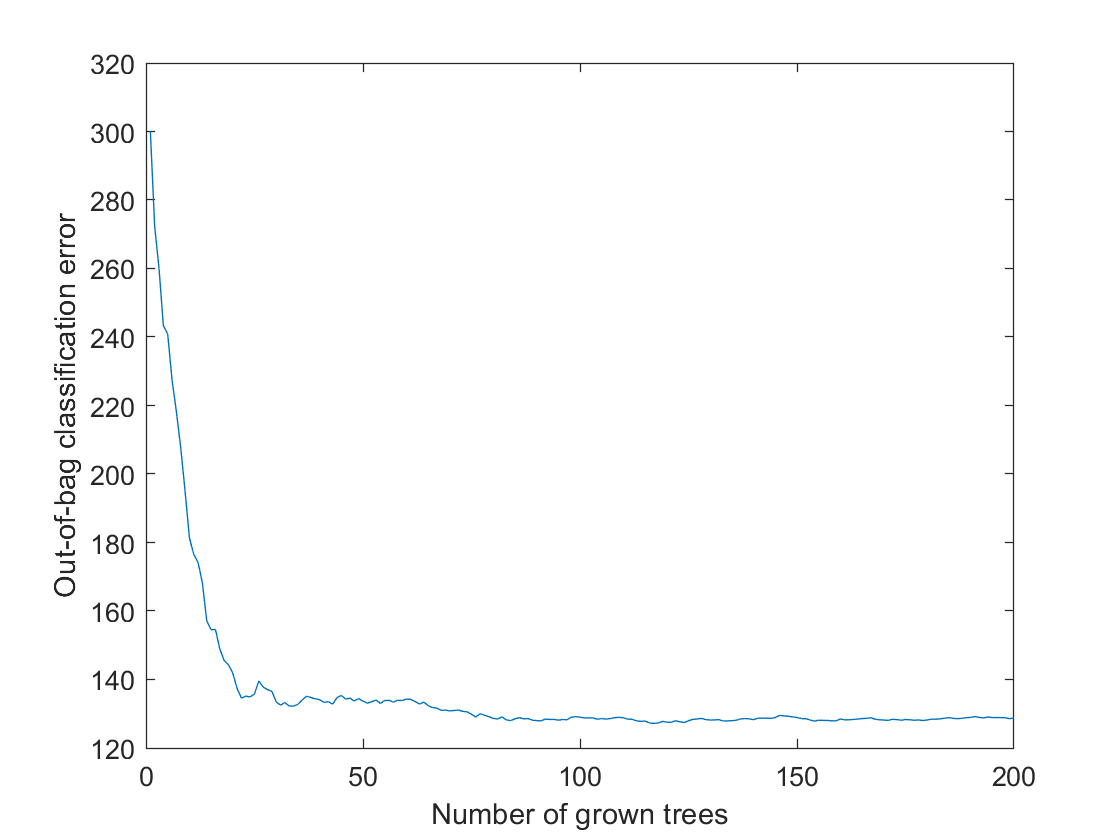

plot(err)
xlabel('Number of grown trees') ;
ylabel('Out-of-bag classification error');

YPred = predict(RFmodel,Xtest) % 

YPred =    39.0214
   52.6618
   38.1825
   47.4347
   56.0993
   59.5930
   61.6275
   61.7495
   40.4714
   34.6039


corr(YPred, Ytest,"rows","complete")

ans = 0.7946

view(RFmodel.Trees{1})


Decision tree for regression
 1  if TotalCholesterol<181.5 then node 2 elseif TotalCholesterol>=181.5 then node 3 else 46.9675
 2  if unknown3_35<2.95389e+06 then node 4 elseif unknown3_35>=2.95389e+06 then node 5 else 30.4372
 3  if unknown0_93<3.28746e+06 then node 6 elseif unknown0_93>=3.28746e+06 then node 7 else 58.2082
 4  if unknown7_79<791590 then node 8 elseif unknown7_79>=791590 then node 9 else 43.4755
 5  if Diacyl_phosphatidyl_cholineC40_3<0.456826 then node 10 elseif Diacyl_phosphatidyl_cholineC40_3>=0.456826 then node 11 else 26.9343
 6  if Unknown0810_amine__traceAnalyte_<770813 then node 12 elseif Unknown0810_amine__traceAnalyte_>=770813 then node 13 else 52.1976
 7  if probablyErythronicAcidTMS4<1.27057e+06 then node 14 elseif probablyErythronicAcidTMS4>=1.27057e+06 then node 15 else 65.858
 8  fit = 35.7396
 9  fit = 51.2114
10  if Glutamine5_mainly_<581493 then node 16 elseif Glutamine5_mainly_>=581493 then node 17 else 25.1316
11  if Creatinine1<1.43871e+06 then n